load boundaryResults.mat boundaryObject
load Lookups.mat invLookupObject
load plant_specs.mat funcs dims

Lets get the "home" (bottom/resting) position right

global_home = funcs.tfSurfaceToGlobal([dims.WSurface/2, num(unitConvert(-19.5*u.in, u.m))])

global_home =     0.6953   -0.9652


Single target point

target_point = funcs.tfSurfaceToGlobal([0.6953, -0.2984]);

assert(boundaryObject.isInBoundary(target_point),'Target point not in boundary') 
target_l = [invLookupObject.inv_kine_lookup.l1(target_point), invLookupObject.inv_kine_lookup.l2(target_point)]

target_l =     0.9819    0.9819


target_steps = funcs.tfLengthsToSteps(target_l);
disp("Target Steps: ["+target_steps(1)+","+target_steps(2)+"]")

Target Steps: [646,646]


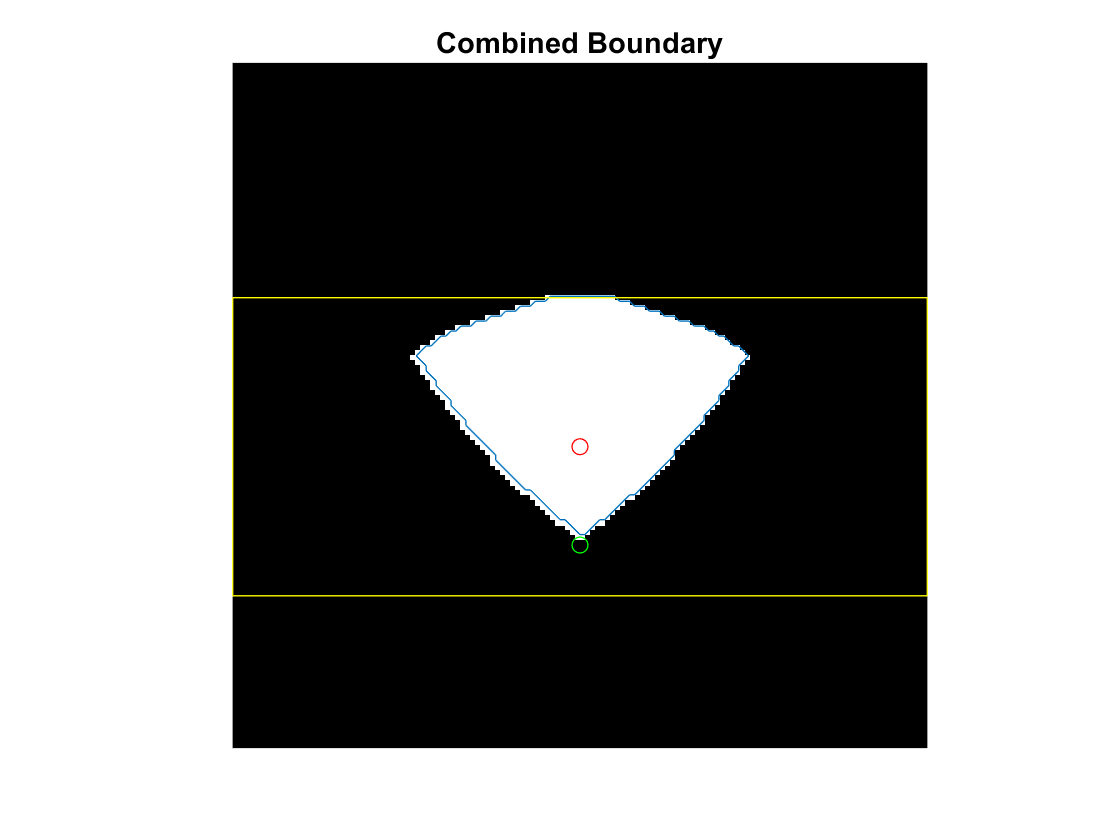

boundaryObject.plotBoundary();
hold on
plot(target_point(1), target_point(2), '-ro')
plot(global_home(1), global_home(2), '-go')
hold off

List of Target Points

target_points = [.4, -.586; 0.6755, -.47; 0.95, -.586; 0.6953, -.7683; .4, -.586];
target_steps = zeros(size(target_points));
for i=1:length(target_points)
    disp("i = "+i)
    t_p = target_points(i,:);
    disp("Target Point: "+t_p)
    assert(boundaryObject.isInBoundary(t_p),'Target point not in boundary');
    t_l = [invLookupObject.inv_kine_lookup.l1(t_p), invLookupObject.inv_kine_lookup.l2(t_p)]
    t_s = funcs.tfLengthsToSteps(t_l);
    target_steps(i,:) = t_s;
    disp("Target Steps: ["+t_s(1)+","+t_s(2)+"]") 
end

i = 1


    "Target Point: 0.4"    "Target Point: -0.586"



t_l =     0.6457    1.0964


Target Steps: [2051,168]


i = 2


    "Target Point: 0.6755"    "Target Point: -0.47"



t_l =     0.7545    0.7875


Target Steps: [1596,1458]


i = 3


    "Target Point: 0.95"    "Target Point: -0.586"



t_l =     1.0597    0.6695


Target Steps: [321,1951]


i = 4


    "Target Point: 0.6953"    "Target Point: -0.7683"



t_l =     0.9819    0.9819


Target Steps: [646,646]


i = 5


    "Target Point: 0.4"    "Target Point: -0.586"



t_l =     0.6457    1.0964


Target Steps: [2051,168]



disp(target_steps)

        2051         168
        1596        1458
         321        1951
         646         646
        2051         168



assert(boundaryObject.isInBoundary(target_points(1,:)),'Target point not in boundary') 


target_l =     0.6457    1.0964
    0.7527    0.7858
    1.0597    0.6695
    0.9819    0.9819
    0.6457    1.0964


Target Steps: [2051,1604]


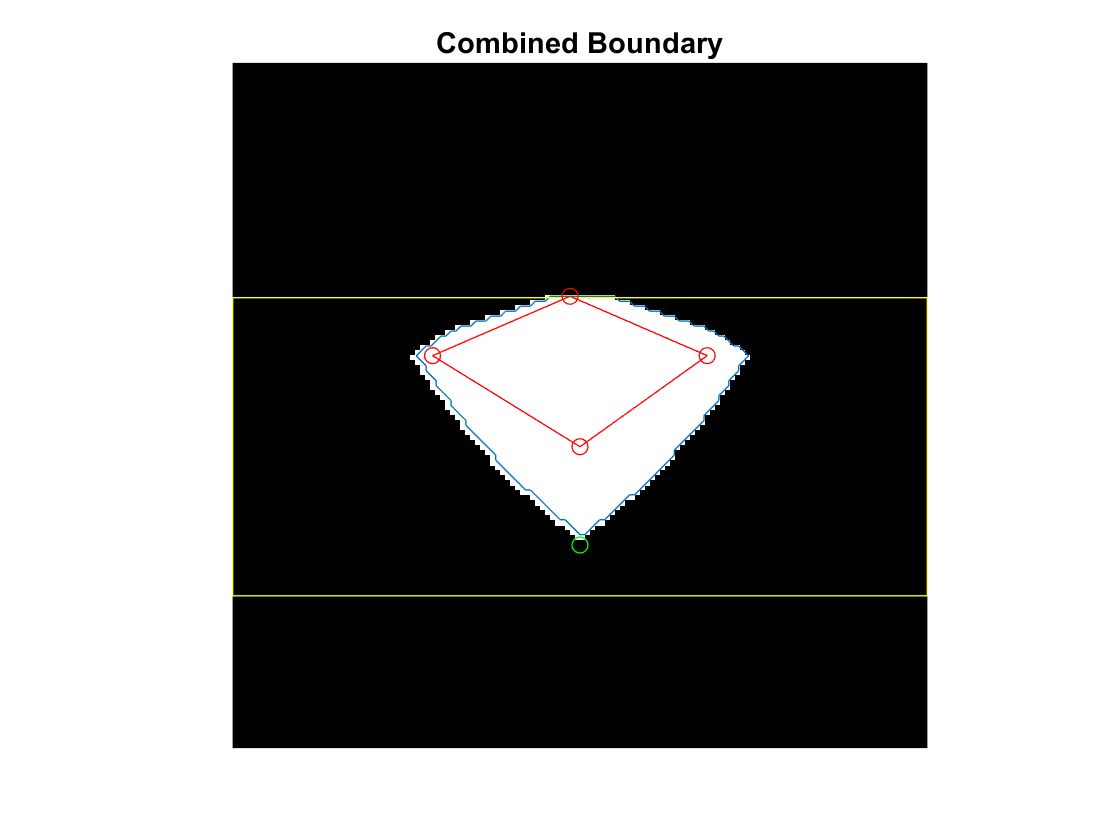

boundaryObject.plotBoundary();
hold on
plot(target_points(:,1), target_points(:,2), '-ro')
plot(global_home(1), global_home(2), '-go')
hold off